# HW5 Q 2 Sadra Safaei 401107198

clc;
clear;

s = tf('s');
G1 = (-s+4)/((s+3)*(s^2 + 2*s +4))

G1 =
 
          -s + 4
  -----------------------
  s^3 + 5 s^2 + 10 s + 12
 
Continuous-time transfer function.



G = G1/s 

G =
 
            -s + 4
  ---------------------------
  s^4 + 5 s^3 + 10 s^2 + 12 s
 
Continuous-time transfer function.




G_feedback = feedback(G*1 , 1)

G_feedback =
 
              -s + 4
  -------------------------------
  s^4 + 5 s^3 + 10 s^2 + 11 s + 4
 
Continuous-time transfer function.



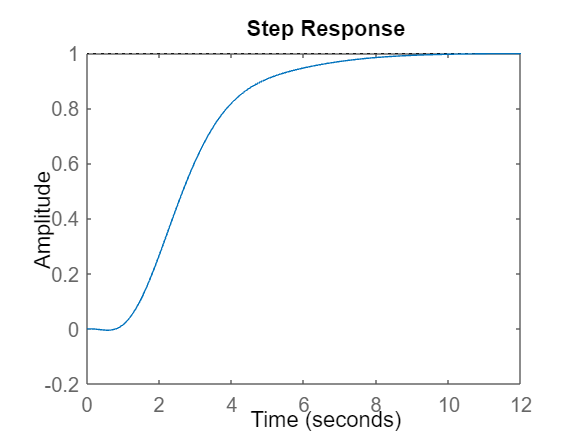

step(G_feedback);


[K_T,L_T,T_T] = get_fod (G1,1);
G_T = K_T*exp(-L_T*s) /(s*(T_T*s+1))

G_T =
 
                 0.3333
  exp(-1.08*s) * ------
                   s
 
Continuous-time transfer function.



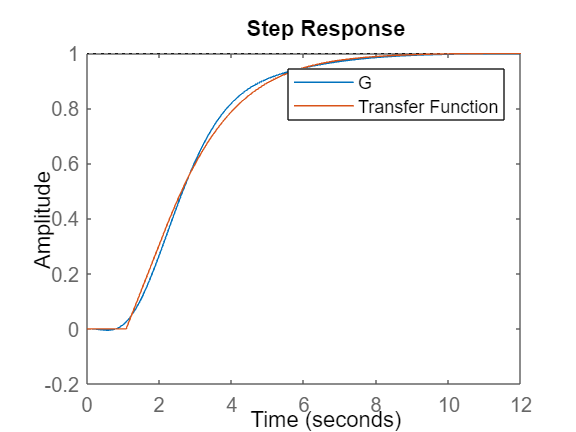


G_Tf = feedback(G_T, 1);

step(G_feedback, G_Tf);
legend ('G' , 'Transfer Function')

## Controller PD

% ISE
[Gc_PD_ISE, ~, ~, ~] = ipdtctrl(1, 1, K_T, L_T, 10);  
G_PD_ISE = feedback(G*Gc_PD_ISE, 1);
% ISTE
[Gc_PD_ISTE,  ~, ~, ~] = ipdtctrl(1, 2, K_T, L_T, 10);  
G_PD_ISTE = feedback(G*Gc_PD_ISTE, 1);
% ISTSE
[Gc_PD_ISTSE,  ~, ~, ~] = ipdtctrl(1, 3, K_T, L_T, 10);  
G_PD_ISTSE = feedback(G*Gc_PD_ISTSE, 1);
Gc_PD_ISTSE

Gc_PD_ISTSE =
 
  1.337 s + 2.492
  ---------------
   0.04875 s + 1
 
Continuous-time transfer function.



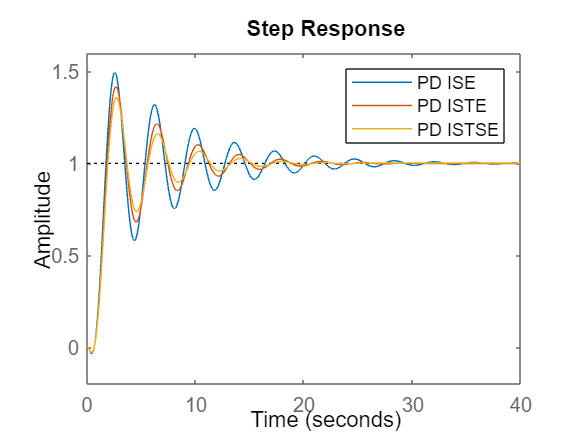

step(G_PD_ISE, G_PD_ISTE, G_PD_ISTSE);
legend('PD ISE', 'PD ISTE', 'PD ISTSE')

## Controller PID

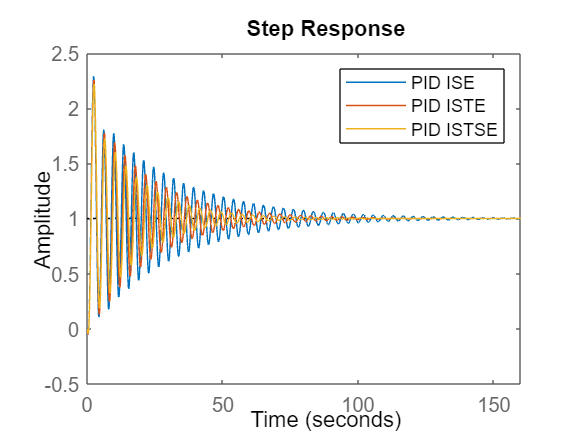

% ISE
[Gc_PID_ISE, ~, ~, ~] = ipdtctrl(2, 1, K_T, L_T, 1000);  
G_PID_ISE = feedback(G*Gc_PID_ISE, 1);
% ISTE
[Gc_PID_ISTE,  ~, ~, ~] = ipdtctrl(2, 2, K_T, L_T, 1000);  
G_PID_ISTE = feedback(G*Gc_PID_ISTE, 1);
% ISTSE
[Gc_PID_ISTSE,  ~, ~, ~] = ipdtctrl(2, 3, K_T, L_T, 1000);  
G_PID_ISTSE = feedback(G*Gc_PID_ISTSE, 1);

step(G_PID_ISE, G_PID_ISTE, G_PID_ISTSE);
legend('PID ISE', 'PID ISTE', 'PID ISTSE')